10.12（成圆算法）实时脚本

由张志涌编写、修改于 2023.1。

#### 注意：    在运行本文件时，请不要直接点击 [运行] 图标！

####                而应把“光标分别放在各节中，然后点击 [运行节] 图标！！

粗糙圆

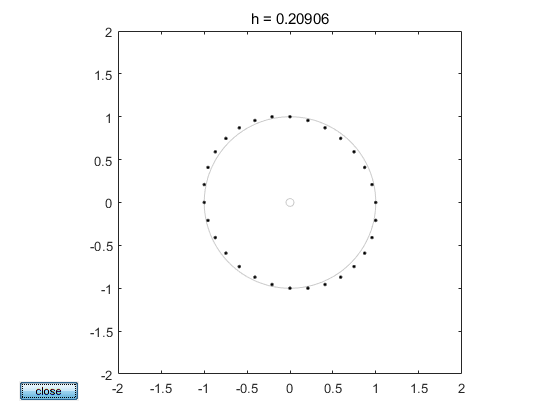

circlegen

精细圆

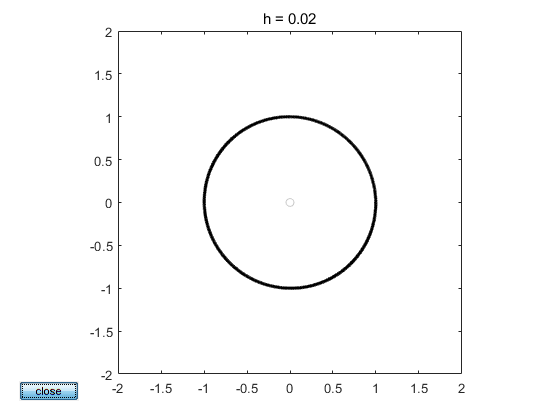

circlegen(0.02)

元素绝对值小于2的随机成圆矩阵有模1特征根

h = 2*rand,A = [1,h;-h,1-h^2],lambda = eig(A),abs(lambda)

h = 0.0480

A =     1.0000    0.0480
   -0.0480    0.9977


lambda =    0.9988 + 0.0479i
   0.9988 - 0.0479i


ans =      1
     1


符号法验证

syms h positive
assumeAlso(h<2)
A=[1,h;-h,1-h^2]

$$A = \left(\begin{array}{cc} 1 & h\\ -h & 1-h^{2} \end{array}\right)$$

eA=eig(A);
lambda=simplify(real(eA)+1i*imag(eA))

$$lambda = \left(\begin{array}{c} 1-\frac{h^{2}}{2}-\frac{h\,\sqrt{4-h^{2}}\,\mathrm{i}}{2}\\ 1-\frac{h^{2}}{2}+\frac{h\,\sqrt{4-h^{2}}\,\mathrm{i}}{2} \end{array}\right)$$

theta=acos(1-h^2/2);
csA=[cos(theta)-1i*sin(theta); cos(theta)+1i*sin(theta)];
Lambda=simplify(real(eA)+1i*imag(csA))

$$Lambda = \left(\begin{array}{c} 1-\frac{h^{2}}{2}-\frac{h\,\sqrt{4-h^{2}}\,\mathrm{i}}{2}\\ 1-\frac{h^{2}}{2}+\frac{h\,\sqrt{4-h^{2}}\,\mathrm{i}}{2} \end{array}\right)$$

diff=simplify(lambda-Lambda)

$$diff = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$